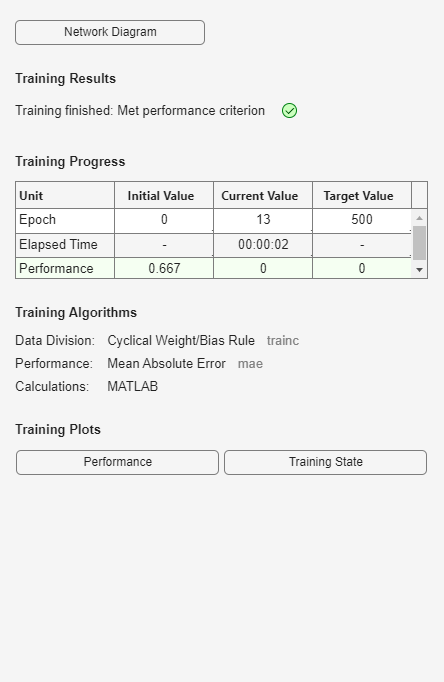

%福冈归属的感知器判别（基于原始数据）
clear                                       %清理内存
P=[15.7 16.3 17.2 18.8 17.9 16.3
970 1260 1422 1874 1698 976
2209 2085 1726 1709 1848 1239
-20.6 -17.3	-9.5 -4.9 -4.5 -4.6
1.9	2.8	4.6	8 7.5 5.6];                     %训练样本输入变量
T=[1 1 0 0 0 0];                            %目标输出
Q=[16.2 1492.0 2000.0 -8.2 6.2]';           %待判样品信息
net=newp(minmax(P),1);                      %构建一个单输出感知器网络
net.trainParam.epochs=500;                  %指定最大训练次数
net=train(net,P,T);                         %网络训练

Yp=sim(net,P)                               %训练样品的预报结果

Yp =      1     1     0     0     0     0


Y=sim(net,Q)                                %给出待判样品的仿真结果

Y = 0